## 1) Load the data 

Load the CIFAR training and test data. Each image is a 32x32 RGB image and there are 15,000 training samples, 3000 test samples. 

clear all; clc; close all;


%Add code
%Load the CIFAR_3.mat

load('CIFAR_3.mat'); 






numImageCategories = 3;
categories(YTrain)

ans = 3×1 cell array
    {'airplane'  }
    {'automobile'}
    {'horse'     }


## 2)**Visualize ** **the CIFAR Dataset**

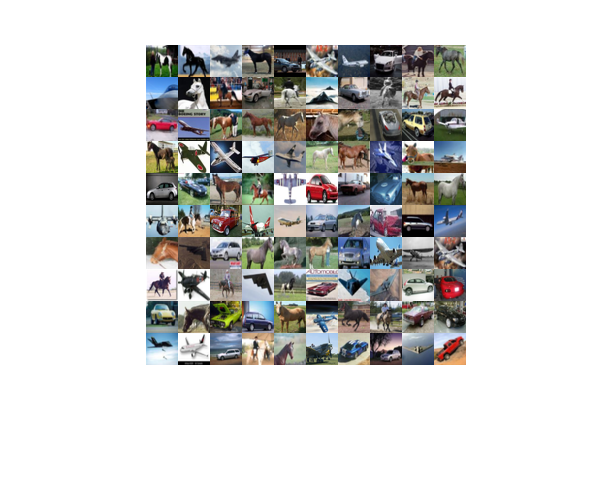

%add code
% Randomly select 100 data points from the training data to display

% [x, y, Num_dim, NumSamples ] = size(XTrain);
% indices = 100;  %returns a row vector containing a random permutation of the integers from 1 to n inclusive.
% image_sel = XTrain(x, y, Num_dim, 1:indices);
% displayData(image_sel); 

[x, y, Num_dim, numSample ] = size(XTrain);
perm = randperm(numel(YTrain), 100); % numel: Number of array elements
img_sel = XTrain(:,:,:,perm);
montage(img_sel)

## **3) Create A Convolutional Neural Network (CNN)**

A CNN is composed of a series of layers, where each layer defines a  specific computation. The Neural Network Toolbox™ provides functionality to easily design a CNN layer-by-layer. In this example, the following  layers are used to create a CNN:

- [`imageInputLayer`](https://www.mathworks.com/help/nnet/ref/nnet.cnn.layer.imageinputlayer.html) - Image input layer

- [`convolution2dLayer`](https://www.mathworks.com/help/nnet/ref/nnet.cnn.layer.convolution2dlayer.html) - 2D convolution layer for Convolutional Neural Networks

- [`reluLayer`](https://www.mathworks.com/help/nnet/ref/nnet.cnn.layer.relulayer.html) - Rectified linear unit (ReLU) layer

- [`maxPooling2dLayer`](https://www.mathworks.com/help/nnet/ref/nnet.cnn.layer.maxpooling2dlayer.html) - Max pooling layer

- [`fullyConnectedLayer`](https://www.mathworks.com/help/nnet/ref/nnet.cnn.layer.fullyconnectedlayer.html) - Fully connected layer

- [`softmaxLayer`](https://www.mathworks.com/help/nnet/ref/nnet.cnn.layer.softmaxlayer.html) - Softmax layer

- [`classificationLayer`](https://www.mathworks.com/help/nnet/ref/classificationlayer.html) - Classification output layer for a neural network

## 3-1)imageInputLayer

%add code 
% %An imageInputLayer inputs images to a network and applies data normalization. 
%1) Create the image input layer for 32x32x3 CIFAR images
 

inputLayer = imageInputLayer([x,y,Num_dim]);




## 3-2) Convoution Layers :Feature Extraction

The middle layers are  made up of repeated blocks of convolutional, ReLU (rectified linear  units), and pooling layers. These 3 layers form the core building blocks of convolutional neural networks. 

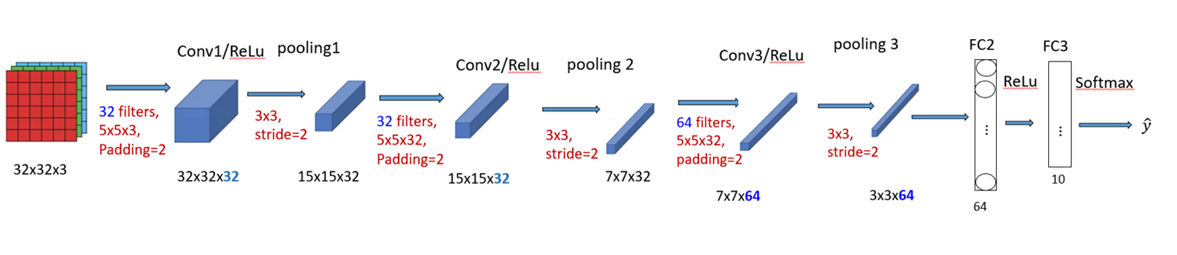

%add code
%Implement the convolution layer of the above CNN architecture
% Convolutional layer parameters

ConvolutionLayers = [convolution2dLayer(5,32,'Padding', 2, 'Name', 'Conv1');

    
% The first convolutional layer has a bank of 32 5x5x3 filters. A
% symmetric padding of 2 pixels is added to ensure that image borders
% are included in the processing. This is important to avoid
% information at the borders being washed away too early in the
% network.





% Note that the third dimension of the filter can be omitted because it
% is automatically deduced based on the connectivity of the network. In
% this case because this layer follows the image layer, the third
% dimension must be 3 to match the number of channels in the input
% image.

% Next add the ReLU layer:



reluLayer('Name', 'relu1');
% Follow it with a max pooling layer that has a 3x3 spatial pooling area
% and a stride of 2 pixels. This down-samples the data dimensions from
% 32x32 to 15x15.
maxPooling2dLayer(3,'Stride', 2, 'Name', 'Pooling 1');






%Build the second and tird convlution layers accrdingly 

convolution2dLayer(15,32,'Padding', 2, 'Name', 'Conv2');
reluLayer('Name', 'relu2');
maxPooling2dLayer(3,'Stride', 2, 'Name', 'Pooling 2');
convolution2dLayer(5,64,'Padding', 2, 'Name', 'Conv3');
reluLayer('Name', 'relu3');
maxPooling2dLayer(3,'Stride', 2,'Name', 'Pooling 3');







]

ConvolutionLayers =   8x1 Layer array with layers:

     1   'Conv1'       Convolution   32 5x5 convolutions with stride [1  1] and padding [2  2  2  2]
     2   'relu1'       ReLU          ReLU
     3   'Pooling 1'   Max Pooling   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     4   'relu2'       ReLU          ReLU
     5   'Pooling 2'   Max Pooling   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'Conv2'       Convolution   64 5x5 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu3'       ReLU          ReLU
     8   'Pooling 3'   Max Pooling   3x3 max pooling with stride [2  2] and padding [0  0  0  0]

## 3-3) The final fully connected layers

The final layers of a CNN are typically composed of fully connected layers and a softmax layer. 

 finalLayers = [
    
% Add a fully connected layer with 64 output neurons. The output size of
% this layer will be an array with a length of 64.


fullyConnectedLayer(64, 'Name', 'fc1');




%% Add  ReLu layer
reluLayer('Name', 'relu4');



%add a fully connected layer with 1 output neurons
fullyConnectedLayer(3, 'Name', 'fc2');



% Add the softmax loss layer and classification layer. The final layers use
% the output of the fully connected layer to compute the categorical
% probability distribution over the image classes. During the training
% process, all the network weights are tuned to minimize the loss over this
% categorical distribution.

softmaxLayer('Name', 'sm1');



%Add Classification layer

classificationLayer('Name', 'coutput');




]

finalLayers =   5x1 Layer array with layers:

     1   'fc1'       Fully Connected         64 fully connected layer
     2   'relu4'     ReLU                    ReLU
     3   'fc2'       Fully Connected         3 fully connected layer
     4   'sm1'       Softmax                 softmax
     5   'coutput'   Classification Output   crossentropyex

**3-4) Combine the input,Convolution Layers, and final Fully connected Layers.**


CNNlayers = [
          inputLayer
         ConvolutionLayers
          finalLayers
    ]

CNNlayers =   14x1 Layer array with layers:

     1   ''            Image Input             32x32x3 images with 'zerocenter' normalization
     2   'Conv1'       Convolution             32 5x5 convolutions with stride [1  1] and padding [2  2  2  2]
     3   'relu1'       ReLU                    ReLU
     4   'Pooling 1'   Max Pooling             3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     5   'relu2'       ReLU                    ReLU
     6   'Pooling 2'   Max Pooling             3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'Conv2'       Convolution             64 5x5 convolutions with stride [1  1] and padding [2  2  2  2]
     8   'relu3'       ReLU                    ReLU
     9   'Pooling 3'   Max Pooling             3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'fc1'         Fully Connected         64 fully connected layer
    11   'rel

## **4) Train CNN Using CIFAR Data**

Now that the network architecture is defined, it can be trained using the  CIFAR training data. First, set up the network training algorithm  using the [`trainingOptions`](https://www.mathworks.com/help/nnet/ref/trainingoptions.html) function. The network training algorithm uses Stochastic Gradient  Descent with Momentum (SGDM) with an initial learning rate of 0.001.  The training algorithm is run for 20 epochs.

Train the network using the [`trainNetwork`](https://www.mathworks.com/help/nnet/ref/trainnetwork.html) function. This is a computationally intensive process that takes 10-30  minutes to complete. 

 %add code here for trainingOptions
 
 
 options = trainingOptions('sgdm', 'MaxEpochs',20, 'InitialLearnRate',0.001, 'Plots', 'training-progress')

options =   TrainingOptionsSGDM with properties:

                     Momentum: 0.9000
             InitialLearnRate: 1.0000e-03
    LearnRateScheduleSettings: [1×1 struct]
             L2Regularization: 1.0000e-04
                    MaxEpochs: 20
                MiniBatchSize: 128
                      Verbose: 1
             VerboseFrequency: 50
               ValidationData: []
          ValidationFrequency: 50
           ValidationPatience: 5
                      Shuffle: 'once'
               CheckpointPath: ''
         ExecutionEnvironment: 'auto'
                   WorkerLoad: []
                    OutputFcn: []
                        Plots: 'training-progress'
               SequenceLength: 'longest'
         SequencePaddingValue: 0


 
 
 %add code for Training the CNN architeture with the training data set and options you defined above

 
 net = trainNetwork(XTrain, YTrain, CNNlayers, options)

Training on single CPU.

**5) Validate CIFAR-10 Network Training**

After the network is trained, it should be validated to ensure that training  was successful. First, a quick visualization of the first convolutional  layer's filter weights can help identify any immediate issues with  training. 

%add code
% Extract the first convolutional layer weights and dispaly the weights
% exanmple code: here net is your trainedr CNN netweok:    
%    w = net.Layers(2).Weights;
%   w = rescale(w);
%    montage(w)



%add code to run the network on the test set.

w = net.Layers(1).Weights;
w = rescale(w);
montage(w)


% add code to calculate the accuracy.








%Optional: randomly selecet 10 images from the test set 
%Display the images
%and Predcit the classe of the each image using the trained CNN network





